# Labrador Sea Cyclone Plotting Script

## Reading in all years of data to create nested directories

% Specify the folder where the files live
myFolder = '/mnt/storage6/robin/TempExtFolder/CGRFLab'

myFolder = '/mnt/storage6/robin/TempExtFolder/TEST'

% Check to make sure the folder actually exists. Warn user if it doesn't
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', myFolder);
    uiwait(warndlg(errorMessage));
    myFolder = uigetdir(); % Ask for a new one.
    if myFolder == 0
         % User clicked Cancel
         return;
    end
end

% Create struct containing tables for each year's data.
filePattern = fullfile(myFolder, '*.csv');
CGRFLab = dir(filePattern);
n = length(CGRFLab);

for ix = 1:n
    baseFileName = CGRFLab(ix).name;
    fullFileName = fullfile(CGRFLab(ix).folder, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    % all opts as follows
    opts = delimitedTextImportOptions("NumVariables", 10);
    opts.DataLines = [2, Inf];
    opts.Delimiter = ",";
    opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";
    [CGRFLab(ix).Data] = readtable(fullFileName, opts);
    clear opts
end

Now reading /mnt/storage6/robin/TempExtFolder/TEST/2002_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2003_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2004_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2005_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2006_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2007_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2008_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2009_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2010_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2011_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2012_CGRF_Lab_Candidatestest.csv
Now reading /mnt/storage6/robin/TempExtFolder/TEST/2013_CGRF_Lab_Candidatest

## Import Data (single year)

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
TestCandidates2002 = readtable("/mnt/storage6/robin/TempExtFolder/2002_CGRF_Lab_CandidatesTEST.csv", opts);
clear opts

## Figure (Monthly colour coded track plots for each year)


% Defining variables for the columns in the cyclone data 
% LabCandidatesT = table2array(LabCandidates);
% trackIDT = LabCandidatesT(:, 1);
% monthT = LabCandidatesT(:, [3 8 9]);
% dayT = LabCandidatesT(:, 4);
% hourT = LabCandidatesT(:, 5);
% lon1 = LabCandidatesT(:, 8);
% lat1 = LabCandidatesT(:, 9);
% n =  max(trackIDT);

%sa = {'2002 Labrador Sea ERA5','2003 Labrador Sea ERA5','2004 Labrador Sea ERA5','2005 Labrador Sea ERA5','2006 Labrador Sea ERA5','2007 Labrador Sea ERA5','2008 Labrador Sea ERA5','2009 Labrador Sea ERA5','2010 Labrador Sea ERA5','2011 Labrador Sea ERA5','2012 Labrador Sea ERA5','2013 Labrador Sea ERA5','2014 Labrador Sea ERA5','2015 Labrador Sea ERA5','2016 Labrador Sea ERA5','2017 Labrador Sea ERA5','2018 Labrador Sea ERA5','2019 Labrador Sea ERA5'};
sa = {'2002 Labrador Sea CGRF','2003 Labrador Sea CGRF','2004 Labrador Sea CGRF','2005 Labrador Sea CGRF','2006 Labrador Sea CGRF','2007 Labrador Sea CGRF','2008 Labrador Sea CGRF','2009 Labrador Sea CGRF','2010 Labrador Sea CGRF','2011 Labrador Sea CGRF','2012 Labrador Sea CGRF','2013 Labrador Sea CGRF','2014 Labrador Sea CGRF','2015 Labrador Sea CGRF','2016 Labrador Sea CGRF','2017 Labrador Sea CGRF','2018 Labrador Sea CGRF','2019 Labrador Sea CGRF'};
% cc = colororder(gem12); % gem12 is relatively colorblind-friendly I think
% dd = colororder(glow12);
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880]

for xx = 1:18
    i = max(CGRFLab(xx).Data.track_id);
    Jan = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 1, :); % Defining tables for each month's data
    Feb = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 2, :);
    Mar = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 3, :);
    Apr = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 4, :);
    May = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 5, :);
    Jun = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 6, :);
    Jul = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 7, :);
    Aug = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 8, :);
    Sep = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 9, :);
    Oct = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 10, :);
    Nov = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 11, :);
    Dec = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 12, :);
    for b = 0:i
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',mycolours(1,:)); % colours specified so that DJF will be easy to visualize
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',mycolours(2,:));
        hold on 
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',mycolours(3,:));
        hold on 
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'.-','Color',mycolours(4,:));
        hold on 
        latMay = May.lat(May.track_id == b);
        lonMay = May.lon(May.track_id == b);
        geoplot(latMay,lonMay,'.-','Color',mycolours(5,:));
        hold on 
        latJun = Jun.lat(Jun.track_id == b);
        lonJun = Jun.lon(Jun.track_id == b);
        geoplot(latJun,lonJun,'.-','Color',mycolours(6,:));
        hold on 
        latJul = Jul.lat(Jul.track_id == b);
        lonJul = Jul.lon(Jul.track_id == b);
        geoplot(latJul,lonJul,'.-','Color',mycolours(7,:));
        hold on 
        latAug = Aug.lat(Aug.track_id == b);
        lonAug = Aug.lon(Aug.track_id == b);
        geoplot(latAug,lonAug,'.-','Color',mycolours(8,:));
        hold on 
        latSep = Sep.lat(Sep.track_id == b);
        lonSep = Sep.lon(Sep.track_id == b);
        geoplot(latSep,lonSep,'.-','Color',mycolours(9,:));
        hold on 
        latOct = Oct.lat(Oct.track_id == b);
        lonOct = Oct.lon(Oct.track_id == b);
        geoplot(latOct,lonOct,'.-','Color',mycolours(10,:));
        hold on 
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'.-','Color',mycolours(11,:));
        hold on 
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'.-','Color',mycolours(12,:));
        hold on 
    end
    geobasemap('topographic')
    title(sa(xx))
    exportgraphics(gca, ['Tracks' num2str(xx+2001) 'LabTEST.png'],"Resolution",300);
    clf
end

## Plotting one year

% All you have to change is the value of xx to produce titled plots for different years
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880]

mycolours =          0    0.4470    0.7410
    0.9490    0.4030    0.7720
    0.4940    0.1840    0.5560
    0.9290    0.6940    0.1250
    0.3010    0.7450    0.9330
    1.0000    0.8390    0.0390
    0.7960    0.5170    0.3640
    1.0000    0.2700    0.2270
    0.6350    0.0780    0.1840
         0    0.6390    0.6390


i = max(TestCandidates2002.track_id);
sa = {'2002 Labrador Sea ERA5','2003 Labrador Sea ERA5','2004 Labrador Sea ERA5','2005 Labrador Sea ERA5','2006 Labrador Sea ERA5','2007 Labrador Sea ERA5','2008 Labrador Sea ERA5','2009 Labrador Sea ERA5','2010 Labrador Sea ERA5','2011 Labrador Sea ERA5','2012 Labrador Sea ERA5','2013 Labrador Sea ERA5','2014 Labrador Sea ERA5','2015 Labrador Sea ERA5','2016 Labrador Sea ERA5','2017 Labrador Sea ERA5','2018 Labrador Sea ERA5','2019 Labrador Sea ERA5'};

xx = 1

xx = 1

Jan = TEST(xx).Data(TEST(xx).Data.month == 1, :); % Defining tables for each month's data
Feb = TEST(xx).Data(TEST(xx).Data.month == 2, :);
Mar = TEST(xx).Data(TEST(xx).Data.month == 3, :);
Apr = TEST(xx).Data(TEST(xx).Data.month == 4, :);
May = TEST(xx).Data(TEST(xx).Data.month == 5, :);
Jun = TEST(xx).Data(TEST(xx).Data.month == 6, :);
Jul = TEST(xx).Data(TEST(xx).Data.month == 7, :);
Aug = TEST(xx).Data(TEST(xx).Data.month == 8, :);
Sep = TEST(xx).Data(TEST(xx).Data.month == 9, :);
Oct = TEST(xx).Data(TEST(xx).Data.month == 10, :);
Nov = TEST(xx).Data(TEST(xx).Data.month == 11, :);
Dec = TEST(xx).Data(TEST(xx).Data.month == 12, :);
for b = 0:i
    latJan = Jan.lat(Jan.track_id == b);
    lonJan = Jan.lon(Jan.track_id == b);
    geoplot(latJan,lonJan,'.-','Color',mycolours(1,:)); % colours specified so that DJF will be easy to visualize
    hold on
    latFeb = Feb.lat(Feb.track_id == b);
    lonFeb = Feb.lon(Feb.track_id == b);
    geoplot(latFeb,lonFeb,'.-','Color',mycolours(2,:));
    hold on 
    latMar = Mar.lat(Mar.track_id == b);
    lonMar = Mar.lon(Mar.track_id == b);
    geoplot(latMar,lonMar,'.-','Color',mycolours(3,:));
    hold on 
    latApr = Apr.lat(Apr.track_id == b);
    lonApr = Apr.lon(Apr.track_id == b);
    geoplot(latApr,lonApr,'.-','Color',mycolours(4,:));
    hold on 
    latMay = May.lat(May.track_id == b);
    lonMay = May.lon(May.track_id == b);
    geoplot(latMay,lonMay,'.-','Color',mycolours(5,:));
    hold on 
    latJun = Jun.lat(Jun.track_id == b);
    lonJun = Jun.lon(Jun.track_id == b);
    geoplot(latJun,lonJun,'.-','Color',mycolours(6,:));
    hold on 
    latJul = Jul.lat(Jul.track_id == b);
    lonJul = Jul.lon(Jul.track_id == b);
    geoplot(latJul,lonJul,'.-','Color',mycolours(7,:));
    hold on 
    latAug = Aug.lat(Aug.track_id == b);
    lonAug = Aug.lon(Aug.track_id == b);
    geoplot(latAug,lonAug,'.-','Color',mycolours(8,:));
    hold on 
    latSep = Sep.lat(Sep.track_id == b);
    lonSep = Sep.lon(Sep.track_id == b);
    geoplot(latSep,lonSep,'.-','Color',mycolours(9,:));
    hold on 
    latOct = Oct.lat(Oct.track_id == b);
    lonOct = Oct.lon(Oct.track_id == b);
    geoplot(latOct,lonOct,'.-','Color',mycolours(10,:));
    hold on 
    latNov = Nov.lat(Nov.track_id == b);
    lonNov = Nov.lon(Nov.track_id == b);
    geoplot(latNov,lonNov,'.-','Color',mycolours(11,:));
    hold on 
    latDec = Dec.lat(Dec.track_id == b);
    lonDec = Dec.lon(Dec.track_id == b);
    geoplot(latDec,lonDec,'.-','Color',mycolours(12,:));
    hold on 
end

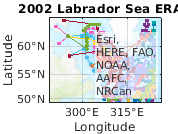

geobasemap('topographic')
title(sa(xx))

%     exportgraphics(gca, ['Tracks' num2str(xx+2001) 'LabERA5.png'],"Resolution",300);

## Exporting the figure

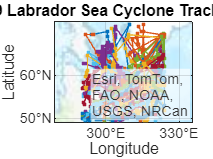

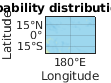

SWITCH expression must be a scalar or a character vector.

exportgraphics(gca,"LabERA52019.png","Resolution",300)

## Defining tables for each month's data

% will need to add this to the loop from 1:18
% Jan = TEST(xx).Data(TEST(xx).Data.month == 1, :);
% Feb = TEST(xx).Data(TEST(xx).Data.month == 2, :);
% Mar = TEST(xx).Data(TEST(xx).Data.month == 3, :);
% Apr = TEST(xx).Data(TEST(xx).Data.month == 4, :);
% May = TEST(xx).Data(TEST(xx).Data.month == 5, :);
% Jun = TEST(xx).Data(TEST(xx).Data.month == 6, :);
% Jul = TEST(xx).Data(TEST(xx).Data.month == 7, :);
% Aug = TEST(xx).Data(TEST(xx).Data.month == 8, :);
% Sep = TEST(xx).Data(TEST(xx).Data.month == 9, :);
% Oct = TEST(xx).Data(TEST(xx).Data.month == 10, :);
% Nov = TEST(xx).Data(TEST(xx).Data.month == 11, :);
% Dec = TEST(xx).Data(TEST(xx).Data.month == 12, :);

Jan = TestCandidates2002(TestCandidates2002.month == 1, :);
Feb = TestCandidates2002(TestCandidates2002.month == 2, :);
Mar = TestCandidates2002(TestCandidates2002.month == 3, :);
Apr = TestCandidates2002(TestCandidates2002.month == 4, :);
May = TestCandidates2002(TestCandidates2002.month == 5, :);
Jun = TestCandidates2002(TestCandidates2002.month == 6, :);
Jul = TestCandidates2002(TestCandidates2002.month == 7, :);
Aug = TestCandidates2002(TestCandidates2002.month == 8, :);
Sep = TestCandidates2002(TestCandidates2002.month == 9, :);
Oct = TestCandidates2002(TestCandidates2002.month == 10, :);
Nov = TestCandidates2002(TestCandidates2002.month == 11, :);
Dec = TestCandidates2002(TestCandidates2002.month == 12, :);

## Making monthly plots & colour coding

% cc = orderedcolors("gem12"); % gem12 is relatively colorblind-friendly I think
% dd = orderedcolors("glow12");
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880];

% i = max(TEST(1).Data.track_id);
i = max(TestCandidates2002.track_id);

for b = 0:i
    latJan = Jan.lat(Jan.track_id == b);
    lonJan = Jan.lon(Jan.track_id == b);
    geoplot(latJan,lonJan,'Color',mycolours(1,:)); % colours specified so that DJF will be easy to visualize
    hold on
    latFeb = Feb.lat(Feb.track_id == b);
    lonFeb = Feb.lon(Feb.track_id == b);
    geoplot(latFeb,lonFeb,'Color',mycolours(2,:));
    hold on 
    latMar = Mar.lat(Mar.track_id == b);
    lonMar = Mar.lon(Mar.track_id == b);
    geoplot(latMar,lonMar,'Color',mycolours(3,:));
    hold on 
    latApr = Apr.lat(Apr.track_id == b);
    lonApr = Apr.lon(Apr.track_id == b);
    geoplot(latApr,lonApr,'Color',mycolours(4,:));
    hold on 
    latMay = May.lat(May.track_id == b);
    lonMay = May.lon(May.track_id == b);
    geoplot(latMay,lonMay,'Color',mycolours(5,:));
    hold on 
    latJun = Jun.lat(Jun.track_id == b);
    lonJun = Jun.lon(Jun.track_id == b);
    geoplot(latJun,lonJun,'Color',mycolours(6,:));
    hold on 
    latJul = Jul.lat(Jul.track_id == b);
    lonJul = Jul.lon(Jul.track_id == b);
    geoplot(latJul,lonJul,'Color',mycolours(7,:));
    hold on 
    latAug = Aug.lat(Aug.track_id == b);
    lonAug = Aug.lon(Aug.track_id == b);
    geoplot(latAug,lonAug,'Color',mycolours(8,:));
    hold on 
    latSep = Sep.lat(Sep.track_id == b);
    lonSep = Sep.lon(Sep.track_id == b);
    geoplot(latSep,lonSep,'Color',mycolours(9,:));
    hold on 
    latOct = Oct.lat(Oct.track_id == b);
    lonOct = Oct.lon(Oct.track_id == b);
    geoplot(latOct,lonOct,'Color',mycolours(10,:));
    hold on 
    latNov = Nov.lat(Nov.track_id == b);
    lonNov = Nov.lon(Nov.track_id == b);
    geoplot(latNov,lonNov,'Color',mycolours(11,:));
    hold on 
    latDec = Dec.lat(Dec.track_id == b);
    lonDec = Dec.lon(Dec.track_id == b);
    geoplot(latDec,lonDec,'Color',mycolours(12,:));
    hold on 
end

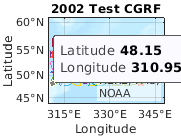

geobasemap('topographic')
title('2002 Test CGRF') 

exportgraphics(gca,"Testplot2002.png","Resolution",300)


## Plotting a single track

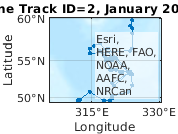

clf
latx = TestCandidates2002.lat(TestCandidates2002.track_id == 2);
lonx = TestCandidates2002.lon(TestCandidates2002.track_id == 2);
geoplot(latx,lonx,'.-')
% hold on
% latxx = TestCandidates2002.lat(TestCandidates2002.track_id == 1);
% lonxx = TestCandidates2002.lon(TestCandidates2002.track_id == 1);
% geoplot(latxx,lonxx,'.-')
geobasemap('topographic')
% title('Tracks 0 and 1, CGRF Test 2002')

title('Cyclone Track ID=2, January 2002 (CGRF)')

## For Testplot: Masking longitude values into -180 - 180

[rows, cols] = size(TestCandidates2002);
TestCandidatesA = table2array(TestCandidates2002);
for k = 1:rows
    if TestCandidatesA(k,8) > 180
        TestCandidatesA(k,8) = (TestCandidatesA(k,8)-360);
        TestCandidates2002 = array2table(TestCandidatesA);
        TestCandidates2002 = renamevars(TestCandidates2002,["TestCandidatesA1","TestCandidatesA2","TestCandidatesA3","TestCandidatesA4","TestCandidatesA5","TestCandidatesA6","TestCandidatesA7","TestCandidatesA8","TestCandidatesA9","TestCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
    end
end


## Geodensityplot

latAll = TestCandidates2002.lat;
lonAll = TestCandidates2002.lon;
geodensityplot(latAll,lonAll)
geobasemap("bluegreen")
title('Cumulative probability distribution of cyclones, 2015')

## Monthly tracks- attempt to use switch

% for b = 0:i
% for LabCandidatesT
%     switch monthT 
%         case LabCandidates.month == 1
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end